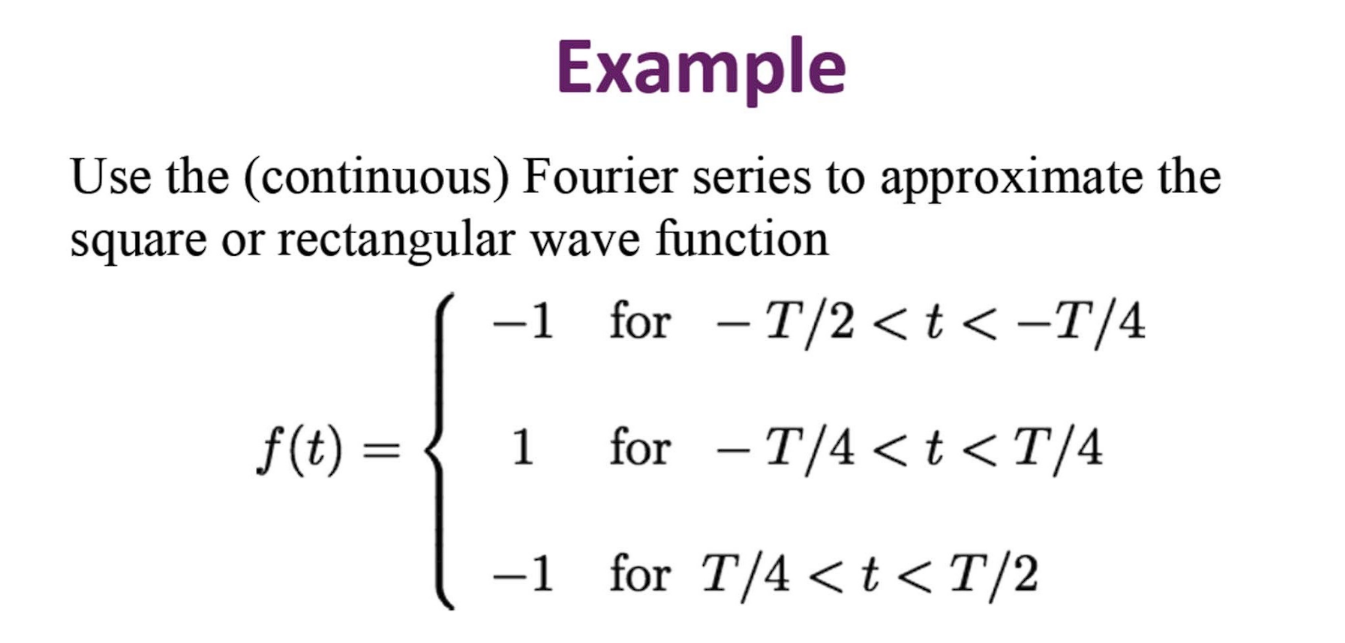

clear
syms n t w T
a0 = 1/T*(int(-1,t,[-T/2 -T/4])+int(1,t,[-T/4 T/4])+int(-1,t,[T/4 T/2]))

$$a0 = 0$$

Find an

an = 2/T*(int(-1*cos(n*w*t),t,[-T/2 -T/4])+int(cos(n*w*t),t,[-T/4 T/4])+int(-1*cos(n*w*t),t,[T/4 T/2]))

$$an = \frac{2\,\left(\frac{2\,\sin\left(\frac{T\,n\,w}{4}\right)}{n\,w}-\frac{2\,\left(\sin\left(\frac{T\,n\,w}{2}\right)-\sin\left(\frac{T\,n\,w}{4}\right)\right)}{n\,w}\right)}{T}$$

Find first term

ft = subs(-2/T*int(cos(n*w*t),t,[-T/2 -T/4]),w*T,2*pi)

$$ft = -\frac{\sin\left(\pi \,n\right)-\sin\left(\frac{\pi \,n}{2}\right)}{n\,\pi }$$

Find second term

st = subs(2/T*int(cos(n*w*t),t,[-T/4 T/4]),w*T,2*pi)

$$st = \frac{2\,\sin\left(\frac{\pi \,n}{2}\right)}{n\,\pi }$$

Find third term

tt = subs(-2/T*int(cos(n*w*t),t,[T/4 T/2]),w*T,2*pi)

$$tt = -\frac{\sin\left(\pi \,n\right)-\sin\left(\frac{\pi \,n}{2}\right)}{n\,\pi }$$

sum of all term

s = zeros(8,1)

s =      0
     0
     0
     0
     0
     0
     0
     0


for n = 1:8
    ft = subs(-2/T*int(cos(n*w*t),t,[-T/2 -T/4]),w*T,2*pi)
    st = subs(2/T*int(cos(n*w*t),t,[-T/4 T/4]),w*T,2*pi)
    tt = subs(-2/T*int(cos(n*w*t),t,[T/4 T/2]),w*T,2*pi)
    s(n) = ft+st+tt
end

$$ft = \frac{1}{\pi }$$

$$st = \frac{2}{\pi }$$

$$tt = \frac{1}{\pi }$$

s =     1.2732
         0
         0
         0
         0
         0
         0
         0


$$ft = 0$$

$$st = 0$$

$$tt = 0$$

s =     1.2732
         0
         0
         0
         0
         0
         0
         0


$$ft = -\frac{1}{3\,\pi }$$

$$st = -\frac{2}{3\,\pi }$$

$$tt = -\frac{1}{3\,\pi }$$

s =     1.2732
         0
   -0.4244
         0
         0
         0
         0
         0


$$ft = 0$$

$$st = 0$$

$$tt = 0$$

s =     1.2732
         0
   -0.4244
         0
         0
         0
         0
         0


$$ft = \frac{1}{5\,\pi }$$

$$st = \frac{2}{5\,\pi }$$

$$tt = \frac{1}{5\,\pi }$$

s =     1.2732
         0
   -0.4244
         0
    0.2546
         0
         0
         0


$$ft = 0$$

$$st = 0$$

$$tt = 0$$

s =     1.2732
         0
   -0.4244
         0
    0.2546
         0
         0
         0


$$ft = -\frac{1}{7\,\pi }$$

$$st = -\frac{2}{7\,\pi }$$

$$tt = -\frac{1}{7\,\pi }$$

s =     1.2732
         0
   -0.4244
         0
    0.2546
         0
   -0.1819
         0


$$ft = 0$$

$$st = 0$$

$$tt = 0$$

s =     1.2732
         0
   -0.4244
         0
    0.2546
         0
   -0.1819
         0


Plot Graph

subplot(2,2,1)
x = -pi:1/1000:pi

x =    -3.1416   -3.1406   -3.1396   -3.1386   -3.1376   -3.1366   -3.1356   -3.1346   -3.1336   -3.1326   -3.1316   -3.1306   -3.1296   -3.1286   -3.1276   -3.1266   -3.1256   -3.1246   -3.1236   -3.1226   -3.1216   -3.1206   -3.1196   -3.1186   -3.1176   -3.1166   -3.1156   -3.1146   -3.1136   -3.1126   -3.1116   -3.1106   -3.1096   -3.1086   -3.1076   -3.1066   -3.1056   -3.1046   -3.1036   -3.1026   -3.1016   -3.1006   -3.0996   -3.0986   -3.0976   -3.0966   -3.0956   -3.0946   -3.0936   -3.0926


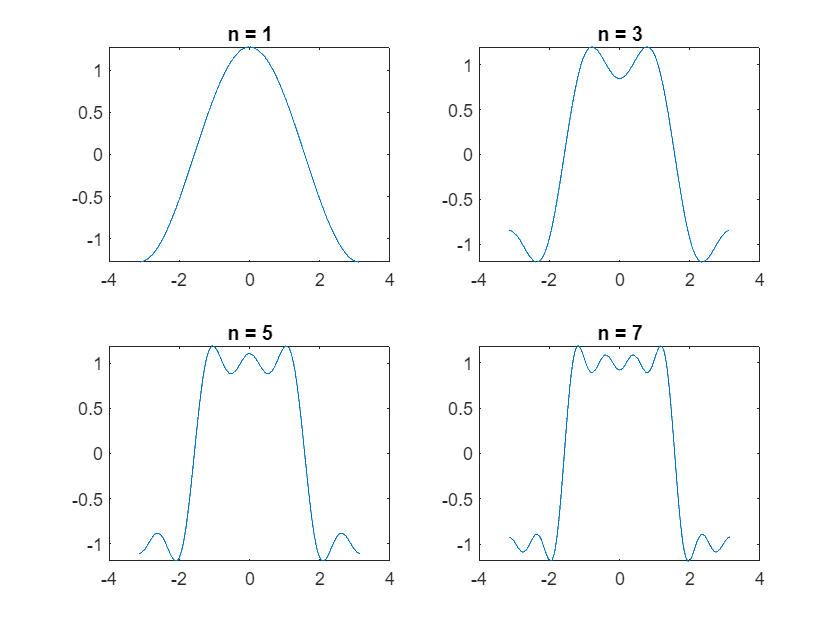

plot(x,s(1)*cos(x))
title("n = 1")

subplot(2,2,2)
plot(x,s(1)*cos(x)+s(3)*cos(3*x))
title("n = 3")

subplot(2,2,3)
plot(x,s(1)*cos(x)+s(3)*cos(3*x)+s(5)*cos(5*x))
title("n = 5")

subplot(2,2,4)
plot(x,s(1)*cos(x)+s(3)*cos(3*x)+s(5)*cos(5*x)+s(7)*cos(7*x))
title("n = 7")

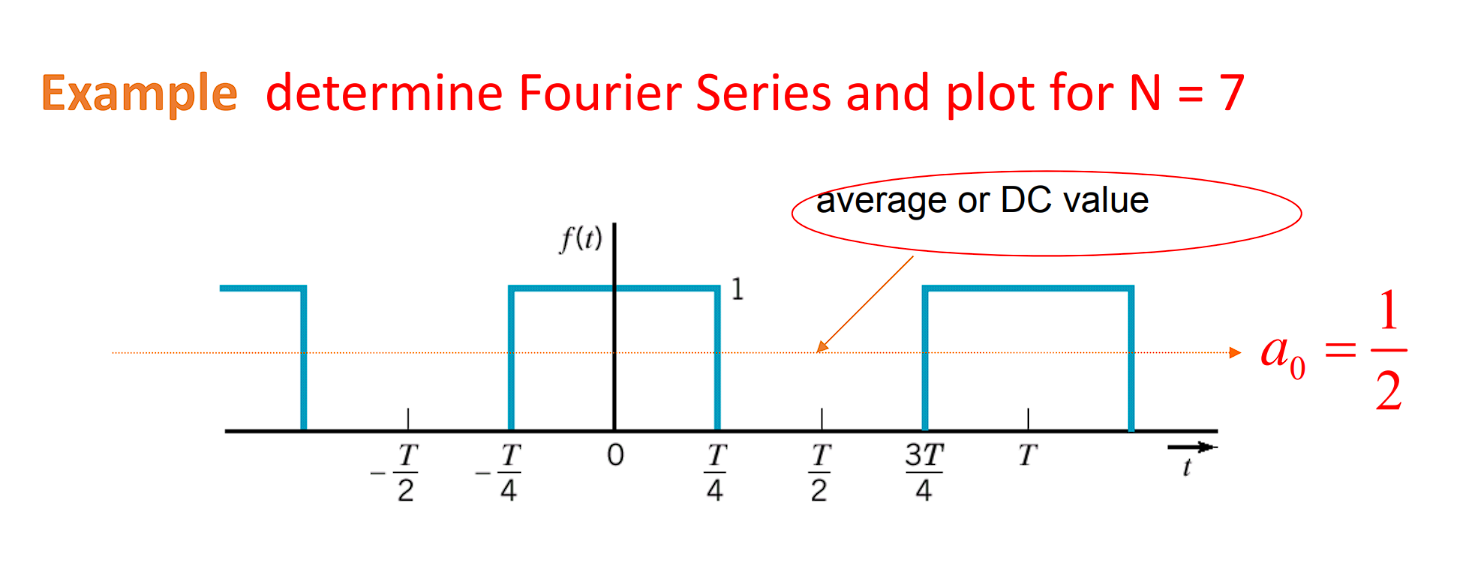

clear
syms T t f(t) t0 n w

a0 = 1/T*int(f(t),t,[t0 t0+T]) == 1/T*int(f(t),t,[-T/2 T/2]) == 1/T*int(1,t,[-T/4 T/4])

$$a0 = \left(\frac{\int_{t_{0}}^{T+t_{0}}f\left(t\right)\mathrm{d}t}{T}=\frac{\int_{-\frac{T}{2}}^{\frac{T}{2}}f\left(t\right)\mathrm{d}t}{T}\right)=\frac{1}{2}$$

An even function exhibits symmetry around the vertical axis at t= 0 so that f(t) = f(-t)

bn = 2/T*int(f(t)*sin(n*w*t),t,[t0 t0+T]) == 2/T*int(1*sin(n*w*t),t,[-T/4 T/4])

$$bn = \frac{2\,\int_{t_{0}}^{T+t_{0}}\sin\left(n\,t\,w\right)\,f\left(t\right)\mathrm{d}t}{T}=0$$

Determine only an

an = subs(2/T*int(1*cos(n*w*t),t,[-T/4 T/4]),T*w,2*pi)

$$an = \frac{2\,\sin\left(\frac{\pi \,n}{2}\right)}{n\,\pi }$$

n 1 ---> 8

k = zeros(8,1)

k =      0
     0
     0
     0
     0
     0
     0
     0


for n = 1:8
    k(n) = subs(2/T*int(1*cos(n*w*t),t,[-T/4 T/4]),T*w,2*pi)
end

k =     0.6366
         0
         0
         0
         0
         0
         0
         0


k =     0.6366
         0
         0
         0
         0
         0
         0
         0


k =     0.6366
         0
   -0.2122
         0
         0
         0
         0
         0


k =     0.6366
         0
   -0.2122
         0
         0
         0
         0
         0


k =     0.6366
         0
   -0.2122
         0
    0.1273
         0
         0
         0


k =     0.6366
         0
   -0.2122
         0
    0.1273
         0
         0
         0


k =     0.6366
         0
   -0.2122
         0
    0.1273
         0
   -0.0909
         0


k =     0.6366
         0
   -0.2122
         0
    0.1273
         0
   -0.0909
         0


Plot

figure;
x = -pi:1/1000:pi

x =    -3.1416   -3.1406   -3.1396   -3.1386   -3.1376   -3.1366   -3.1356   -3.1346   -3.1336   -3.1326   -3.1316   -3.1306   -3.1296   -3.1286   -3.1276   -3.1266   -3.1256   -3.1246   -3.1236   -3.1226   -3.1216   -3.1206   -3.1196   -3.1186   -3.1176   -3.1166   -3.1156   -3.1146   -3.1136   -3.1126   -3.1116   -3.1106   -3.1096   -3.1086   -3.1076   -3.1066   -3.1056   -3.1046   -3.1036   -3.1026   -3.1016   -3.1006   -3.0996   -3.0986   -3.0976   -3.0966   -3.0956   -3.0946   -3.0936   -3.0926


y = 1/2+k(1)*cos(x)+k(3)*cos(3*x)+k(5)*cos(5*x)+k(7)*cos(7*x)

y =     0.0392    0.0392    0.0392    0.0392    0.0392    0.0392    0.0392    0.0391    0.0391    0.0391    0.0391    0.0391    0.0390    0.0390    0.0390    0.0389    0.0389    0.0388    0.0388    0.0387    0.0387    0.0386    0.0386    0.0385    0.0385    0.0384    0.0384    0.0383    0.0382    0.0381    0.0381    0.0380    0.0379    0.0378    0.0377    0.0377    0.0376    0.0375    0.0374    0.0373    0.0372    0.0371    0.0370    0.0369    0.0368    0.0367    0.0365    0.0364    0.0363    0.0362


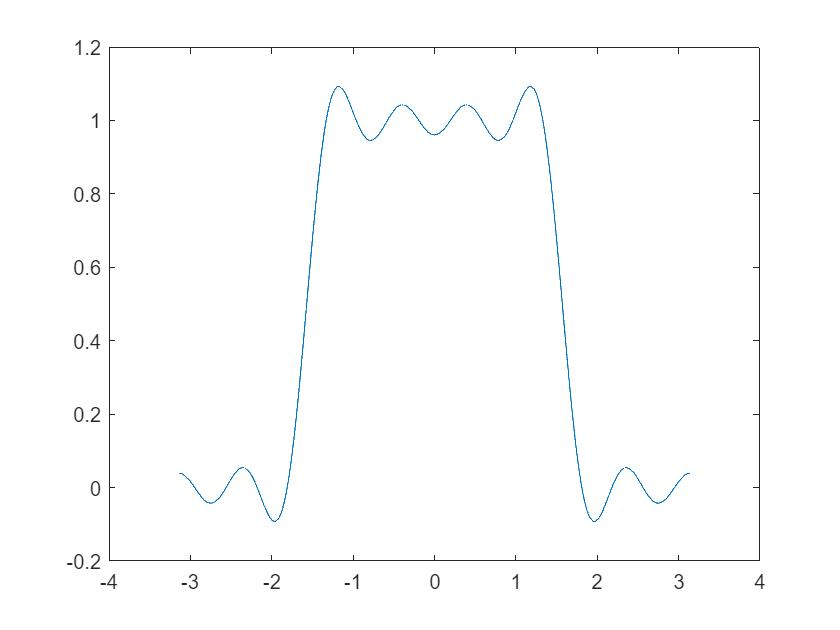

plot(x,y)

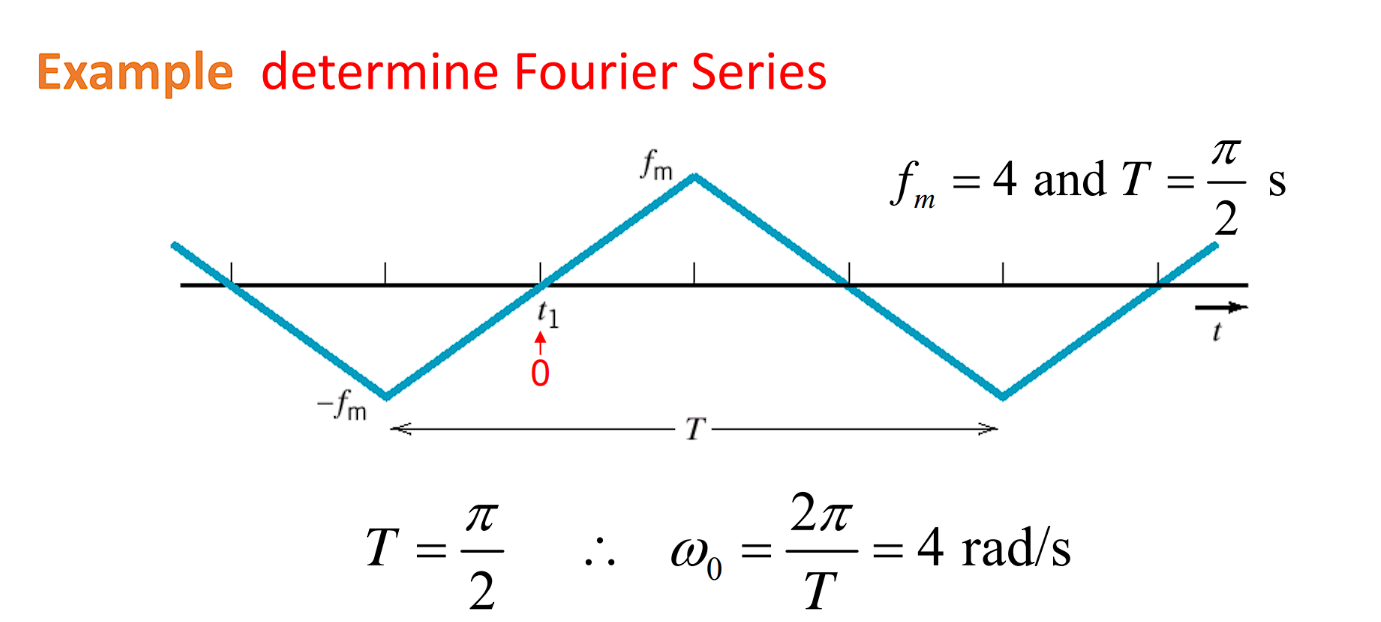

clear
syms t n
fm = 4

fm = 4

T = pi/2

T = 1.5708

w = 2*pi/T

w = 4

ft = eval(fm/(T/4)*t)

$$ft = \frac{5734161139222659\,t}{562949953421312}$$

All an = 0 and bn = 0 for even values of n and a0 = 0

bn = 8/T*int(ft*sin(n*w*t),t,[0 T/4])

$$bn = \frac{32880603970571302491146779030281\,\left(\sin\left(\frac{\pi \,n}{2}\right)-\frac{\pi \,n\,\cos\left(\frac{\pi \,n}{2}\right)}{2}\right)}{10141204801825835211973625643008\,n^{2}}$$

bn = 32/((pi^2)*n^2)*sin(n*pi/2) %for odd n

$$bn = \frac{9007199254740992\,\sin\left(\frac{\pi \,n}{2}\right)}{2778046668940015\,n^{2}}$$

ft = symsum(bn*sin(n*w*t),n,1,7)

$$ft = \frac{9007199254740992\,\sin\left(4\,t\right)}{2778046668940015}-\frac{9007199254740992\,\sin\left(12\,t\right)}{25002420020460135}+\frac{9007199254740992\,\sin\left(20\,t\right)}{69451166723500375}-\frac{9007199254740992\,\sin\left(28\,t\right)}{136124286778060735}$$

Plot

x = -pi:1/100:pi

x =    -3.1416   -3.1316   -3.1216   -3.1116   -3.1016   -3.0916   -3.0816   -3.0716   -3.0616   -3.0516   -3.0416   -3.0316   -3.0216   -3.0116   -3.0016   -2.9916   -2.9816   -2.9716   -2.9616   -2.9516   -2.9416   -2.9316   -2.9216   -2.9116   -2.9016   -2.8916   -2.8816   -2.8716   -2.8616   -2.8516   -2.8416   -2.8316   -2.8216   -2.8116   -2.8016   -2.7916   -2.7816   -2.7716   -2.7616   -2.7516   -2.7416   -2.7316   -2.7216   -2.7116   -2.7016   -2.6916   -2.6816   -2.6716   -2.6616   -2.6516


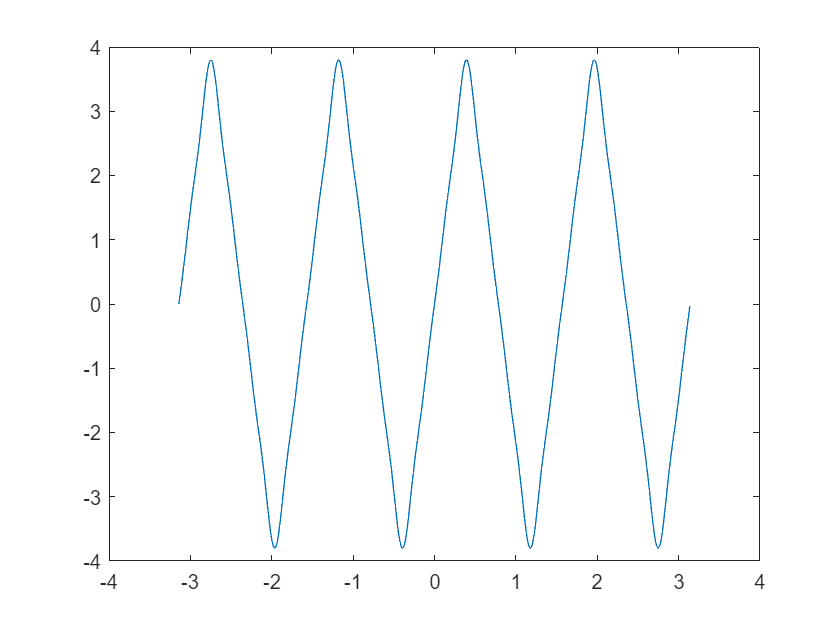

plot(x,symsum(32/((pi^2)*n^2)*sin(n*pi/2)*sin(n*w*x),n,1,7))

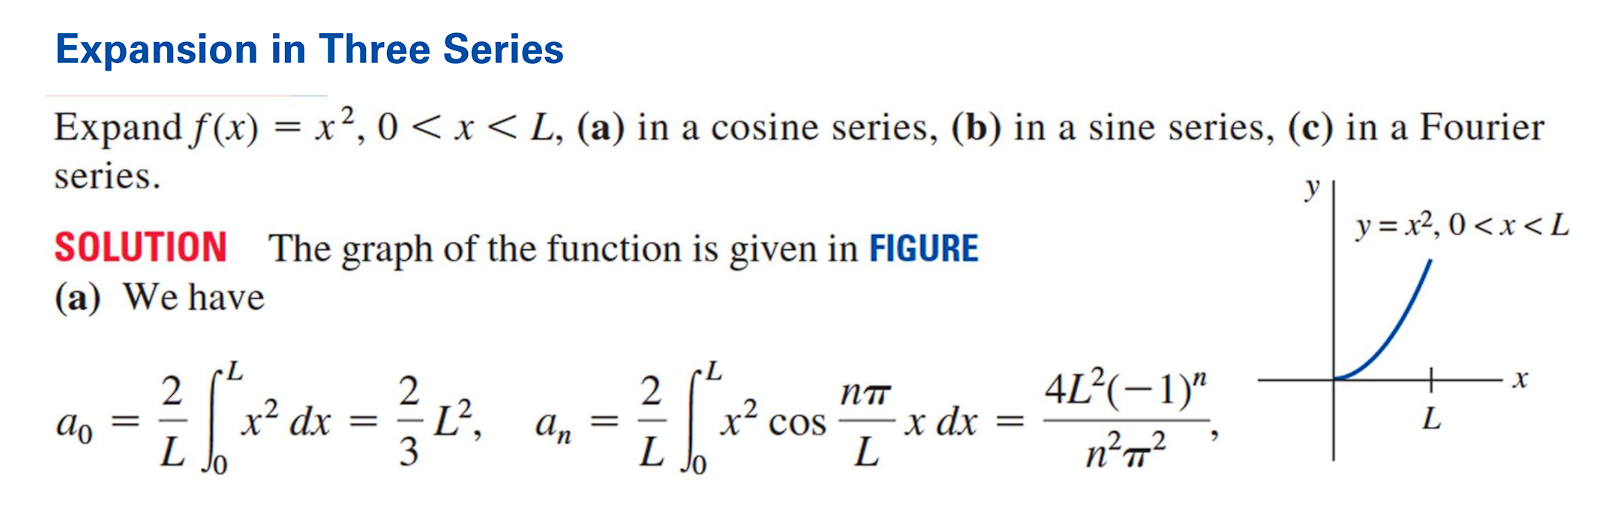

clear
syms x n L

a)

a0 = 2/L*int(x^2,x,[0 L])

$$a0 = \frac{2\,L^{2}}{3}$$

an = 2/L*int(x^2*cos(n*pi*x/L),x,[0 L])

$$an = \frac{2\,\left(L^{3}\,n^{2}\,\pi^{2}\,\sin\left(\pi \,n\right)-2\,L^{3}\,\sin\left(\pi \,n\right)+2\,\pi \,L^{3}\,n\,\cos\left(\pi \,n\right)\right)}{L\,n^{3}\,\pi^{3}}$$

fx = a0 + an*cos(n*pi*x/L)

$$fx = \frac{2\,L^{2}}{3}+\frac{2\,\cos\left(\frac{\pi \,n\,x}{L}\right)\,\left(L^{3}\,n^{2}\,\pi^{2}\,\sin\left(\pi \,n\right)-2\,L^{3}\,\sin\left(\pi \,n\right)+2\,\pi \,L^{3}\,n\,\cos\left(\pi \,n\right)\right)}{L\,n^{3}\,\pi^{3}}$$

% change n 

b)

bn = 2/L*int(x^2*sin(n*pi*x/L),x,[0 L])

$$bn = \frac{2\,L^{2}\,\left(n^{2}\,\pi^{2}\,\left(2\,{\sin\left(\frac{\pi \,n}{2}\right)}^{2}-1\right)-4\,{\sin\left(\frac{\pi \,n}{2}\right)}^{2}+2\,\pi \,n\,\sin\left(\pi \,n\right)\right)}{n^{3}\,\pi^{3}}$$

f1 = bn*sin(n*pi*x/L)

$$f1 = \frac{2\,L^{2}\,\sin\left(\frac{\pi \,n\,x}{L}\right)\,\left(n^{2}\,\pi^{2}\,\left(2\,{\sin\left(\frac{\pi \,n}{2}\right)}^{2}-1\right)-4\,{\sin\left(\frac{\pi \,n}{2}\right)}^{2}+2\,\pi \,n\,\sin\left(\pi \,n\right)\right)}{n^{3}\,\pi^{3}}$$

% change n

c)

a0 = 2/L*int(x^2,x,[0 L])

$$a0 = \frac{2\,L^{2}}{3}$$

an = 2/L*int(x^2*cos(2*n*pi*x/L),x,[0 L])

$$an = \frac{2\,\left(\frac{L^{3}\,n^{2}\,\pi^{2}\,\sin\left(2\,\pi \,n\right)}{2}-\frac{L^{3}\,\sin\left(2\,\pi \,n\right)}{4}+\frac{\pi \,L^{3}\,n\,\cos\left(2\,\pi \,n\right)}{2}\right)}{L\,n^{3}\,\pi^{3}}$$

bn = 2/L*int(x^2*sin(2*n*pi*x/L),x,[0 L])

$$bn = \frac{2\,L^{2}\,\left(n^{2}\,\pi^{2}\,\left({\sin\left(\pi \,n\right)}^{2}-\frac{1}{2}\right)-\frac{{\sin\left(\pi \,n\right)}^{2}}{2}+\frac{\pi \,n\,\sin\left(2\,\pi \,n\right)}{2}\right)}{n^{3}\,\pi^{3}}$$

f = a0 +an*cos(2*n*pi*x/L) + bn*sin(2*n*pi*x/L)

$$f = \begin{array}{l} \frac{2\,L^{2}}{3}+\frac{2\,\cos\left(\sigma_{2}\right)\,\left(\frac{L^{3}\,n^{2}\,\pi^{2}\,\sigma_{1}}{2}-\frac{L^{3}\,\sigma_{1}}{4}+\frac{\pi \,L^{3}\,n\,\cos\left(2\,\pi \,n\right)}{2}\right)}{L\,n^{3}\,\pi^{3}}+\frac{2\,L^{2}\,\sin\left(\sigma_{2}\right)\,\left(n^{2}\,\pi^{2}\,\left(\sigma_{3}-\frac{1}{2}\right)-\frac{\sigma_{3}}{2}+\frac{\pi \,n\,\sigma_{1}}{2}\right)}{n^{3}\,\pi^{3}}\\ \mathrm{where}\\ \sigma_{1}=\sin\left(2\,\pi \,n\right)\\ \sigma_{2}=\frac{2\,\pi \,n\,x}{L}\\ \sigma_{3}={\sin\left(\pi \,n\right)}^{2} \end{array}$$